# Rad229 - Lecture 13:  Sampling and Timing

## lec13_01.m:  General PSF Analysis

Demonstrate the function psf2d.m, which shows a point-spread function.

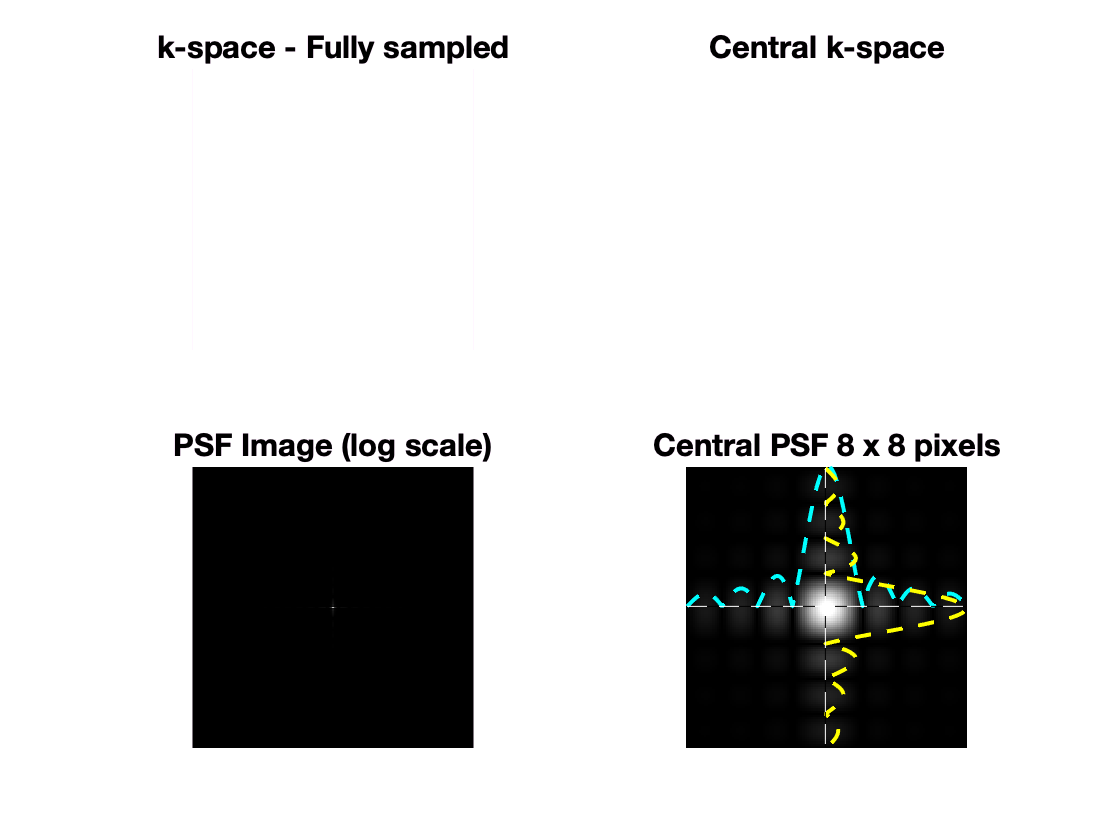

% Lecture 13, Example 01
%
% Plot point-spread functions using psf2d.m

set(0,'defaultAxesFontSize',14);        % Default font sizes
figure(1);
im = psf2d;     % Default, 256x256 k-space.
subplot(2,2,1); title('k-space - Fully sampled');

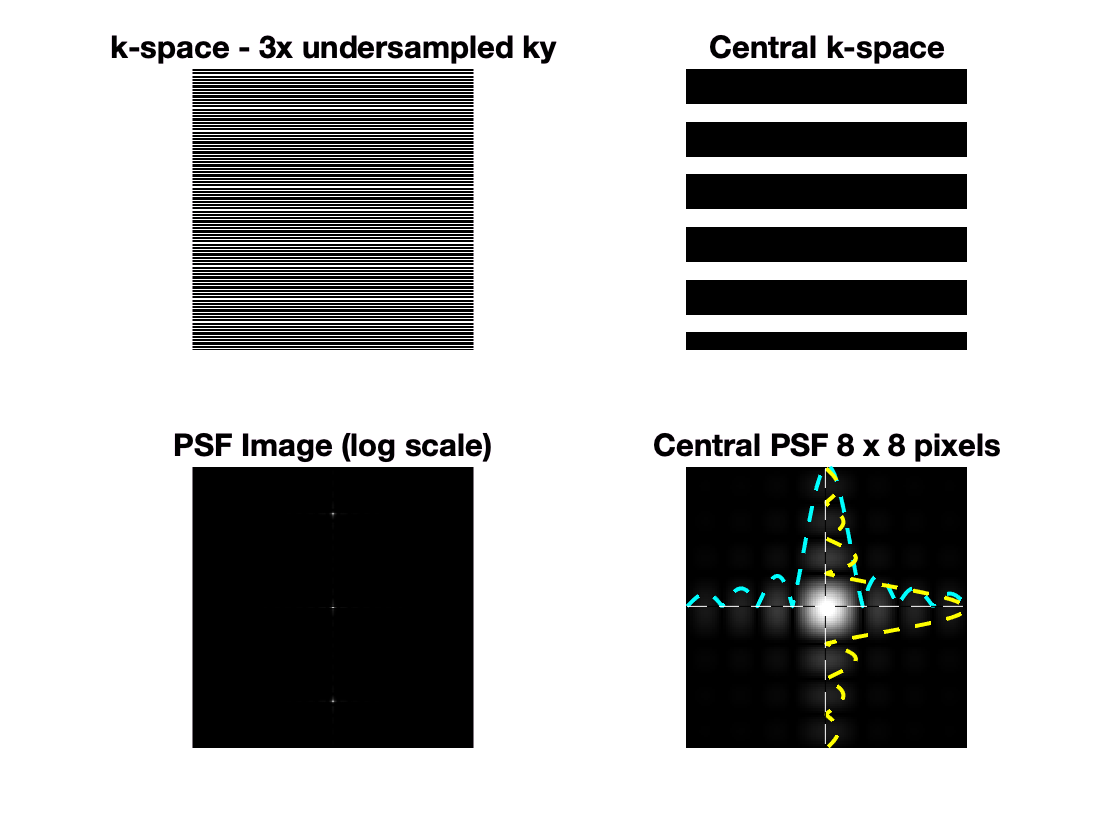


figure(2);
k = ones(256,256);
k(1:3:end,:)=0;
k(2:3:end,:)=0;
im = psf2d(k); 
subplot(2,2,1); title('k-space - 3x undersampled ky');

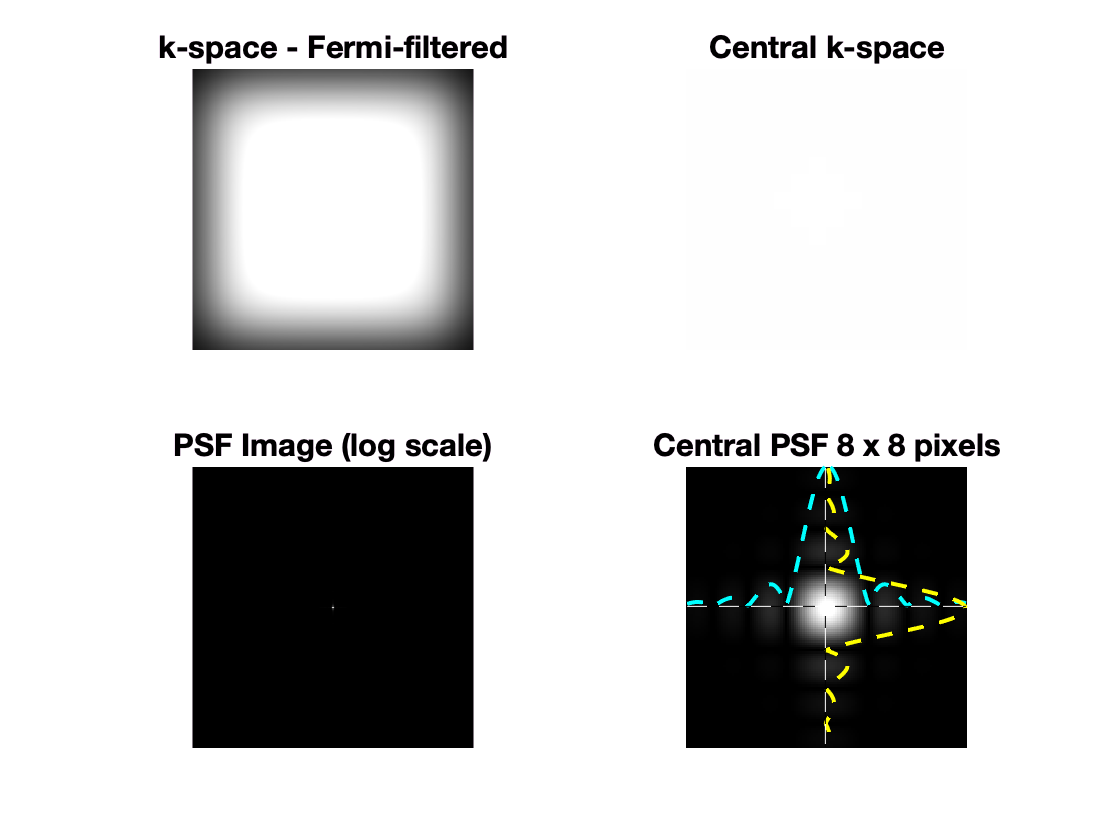


figure(3);
ff = 1./(exp((abs([1:256]-128)-112)/16)+1);
ff = diag(ff); 
k = ones(256,256);
kf = ff*k*ff;   % Apply Fermi filter
im = psf2d(kf); 
subplot(2,2,1); title('k-space - Fermi-filtered');

## lec13_02.m:  Variable-density sampling

Show the PSF that results from variable-density sampling.

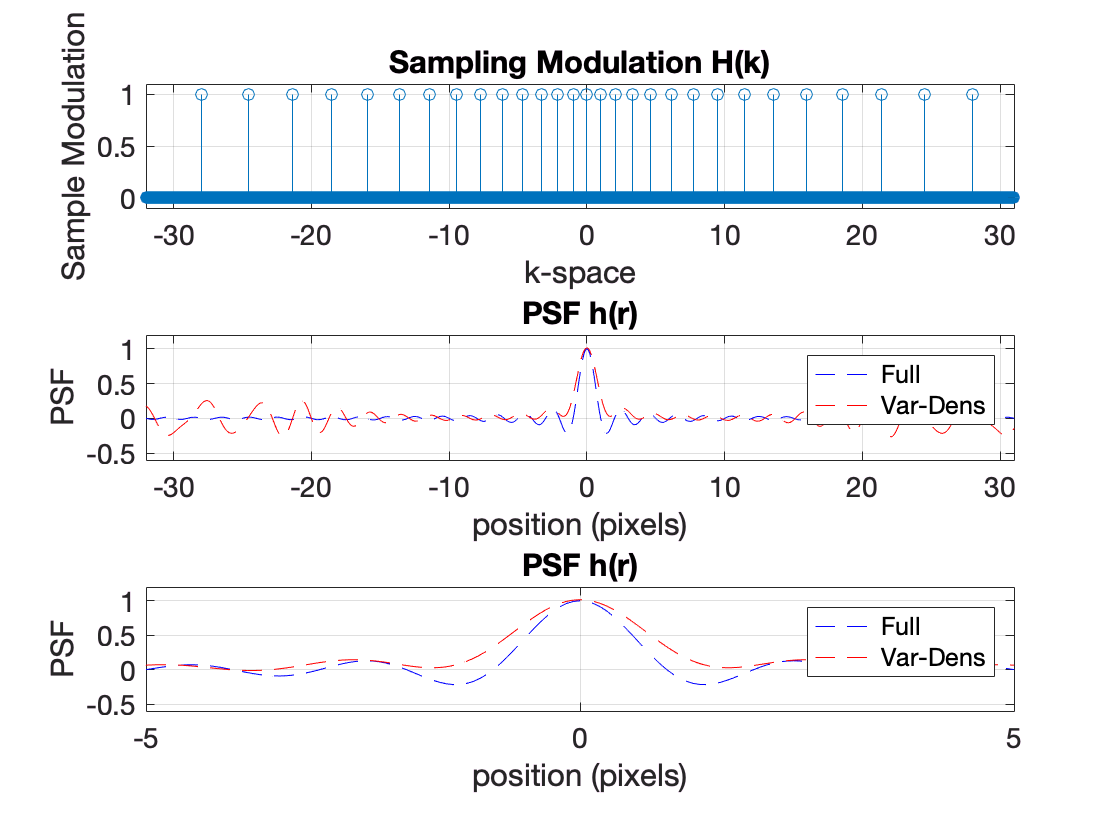

%% Lecture 13 - Example 2
%
% Variable-density sampling (1D)
%
N = 64;
Ni=100;
denscomp=0;                     % Density compensate
kx = [-N/2:1/Ni:N/2-1];         % kx locations
a = .1;                         % Weighting for spacing
dk = 1+a*abs(kx);               % Spacing betweek k-space points
H = 0*kx;

k=0;
fc = find(kx==0);

while k<max(kx)
  [y,imin] = min(abs(kx-k));
  H(imin)=1;
  if (denscomp==1) H(imin)=dk(imin)/max(abs(dk)); end;
  H(2*fc-imin)=H(imin); % Negative point
  k=k+dk(imin);
end;

% -- Calculate PSFs

Hv=H;
sH = sum(Hv);

% -- Full k-space, PSF calculation
Hf = ones(1,N);
H=Hf;
Hpad = [0*H 0*H 0*H 0*H 0*H 0*H H 0*H 0*H 0*H 0*H 0*H 0*H];
hf = ifftshift(ifft(ifftshift(Hpad)))*length(Hpad)/length(Hf);
xf = [0:length(hf)-1]/length(hf)*N-N/2;
hf = hf.* exp(i*pi*xf/64);

% -- VDS k-space, PSF calculation
H = Hv;
Hpad = [0*H 0*H 0*H 0*H 0*H 0*H H 0*H 0*H 0*H 0*H 0*H 0*H];
hv = ifftshift(ifft(ifftshift(Hpad)))*length(Hpad)/length(H)*Ni*N/sH;
xv = (([0:length(hv)-1]-0.5)/length(hv)*N-N/2)*Ni;
hv = hv.* exp(-i*pi*xv/64);

% -- Plots
figure;
subplot(3,1,1)
stem(kx,Hv(:));
axis([-N/2 N/2-1 -.1 1.1]);
lplot('k-space','Sample Modulation','Sampling Modulation H(k)');

subplot(3,1,2)
plot(xf,real(hf),'b--',xv,real(hv),'r--');
lplot('position (pixels)','PSF','PSF h(r)');
axis([-N/2 N/2-1 -.6 1.2]);
legend('Full','Var-Dens');

subplot(3,1,3)
plot(xf,real(hf),'b--',xv,real(hv),'r--');
lplot('position (pixels)','PSF','PSF h(r)');
%axis([-N/2 N/2-1 -.6 1.2]);
axis([-5 5 -.6 1.2]);
legend('Full','Var-Dens');

## lec13_03.m:  Other Sampling PSFs

Here you will try some other sampling schemes, to see the impact of the sampling on the PSF, and an image.

lec13_04.m:  Homodyne Reconstruction

Here you will experiment with homodyne reconstruction of an actual image.

% Lecture 13, Example 04
% 
% Homodyne reconstruction

set(0,'defaultAxesFontSize',14);        % Default font sizes
figure(1);

% -- Generate Sample Data (Array of squares)
[kx,ky] = meshgrid([-128:127]/256,[-128:127]/256);
[cx,cy] = meshgrid(2*[-2:2],2*[-2:2]);
centers = [cx(:)+i*cy(:); [-8; -6; 6; 8]; i*[ -8; -6; 6; 8]]*10;
kdata = ksquare(centers,19,kx+i*ky,0,0); % k-space data

im = ft(kdata); % -- Reconstruct the image

% -- Run the Homodyne example code
imhd = homodyneshow(im,16);
